# ECE 486 S23 Project Section 3

### @author Laurent Zheng (20818351)

## 1. Designing the Arm

The robot arm sits behind and below the cuboid workspace. In the frame {s}, the centre of the base is at [-0.5, 0, -0.5]. The paddle at the home position is at the 0.1 metres below and 0.05 metres behind the workspace, while aligning in the z-axis in frame {s}. We can see this depicted in the following figure.

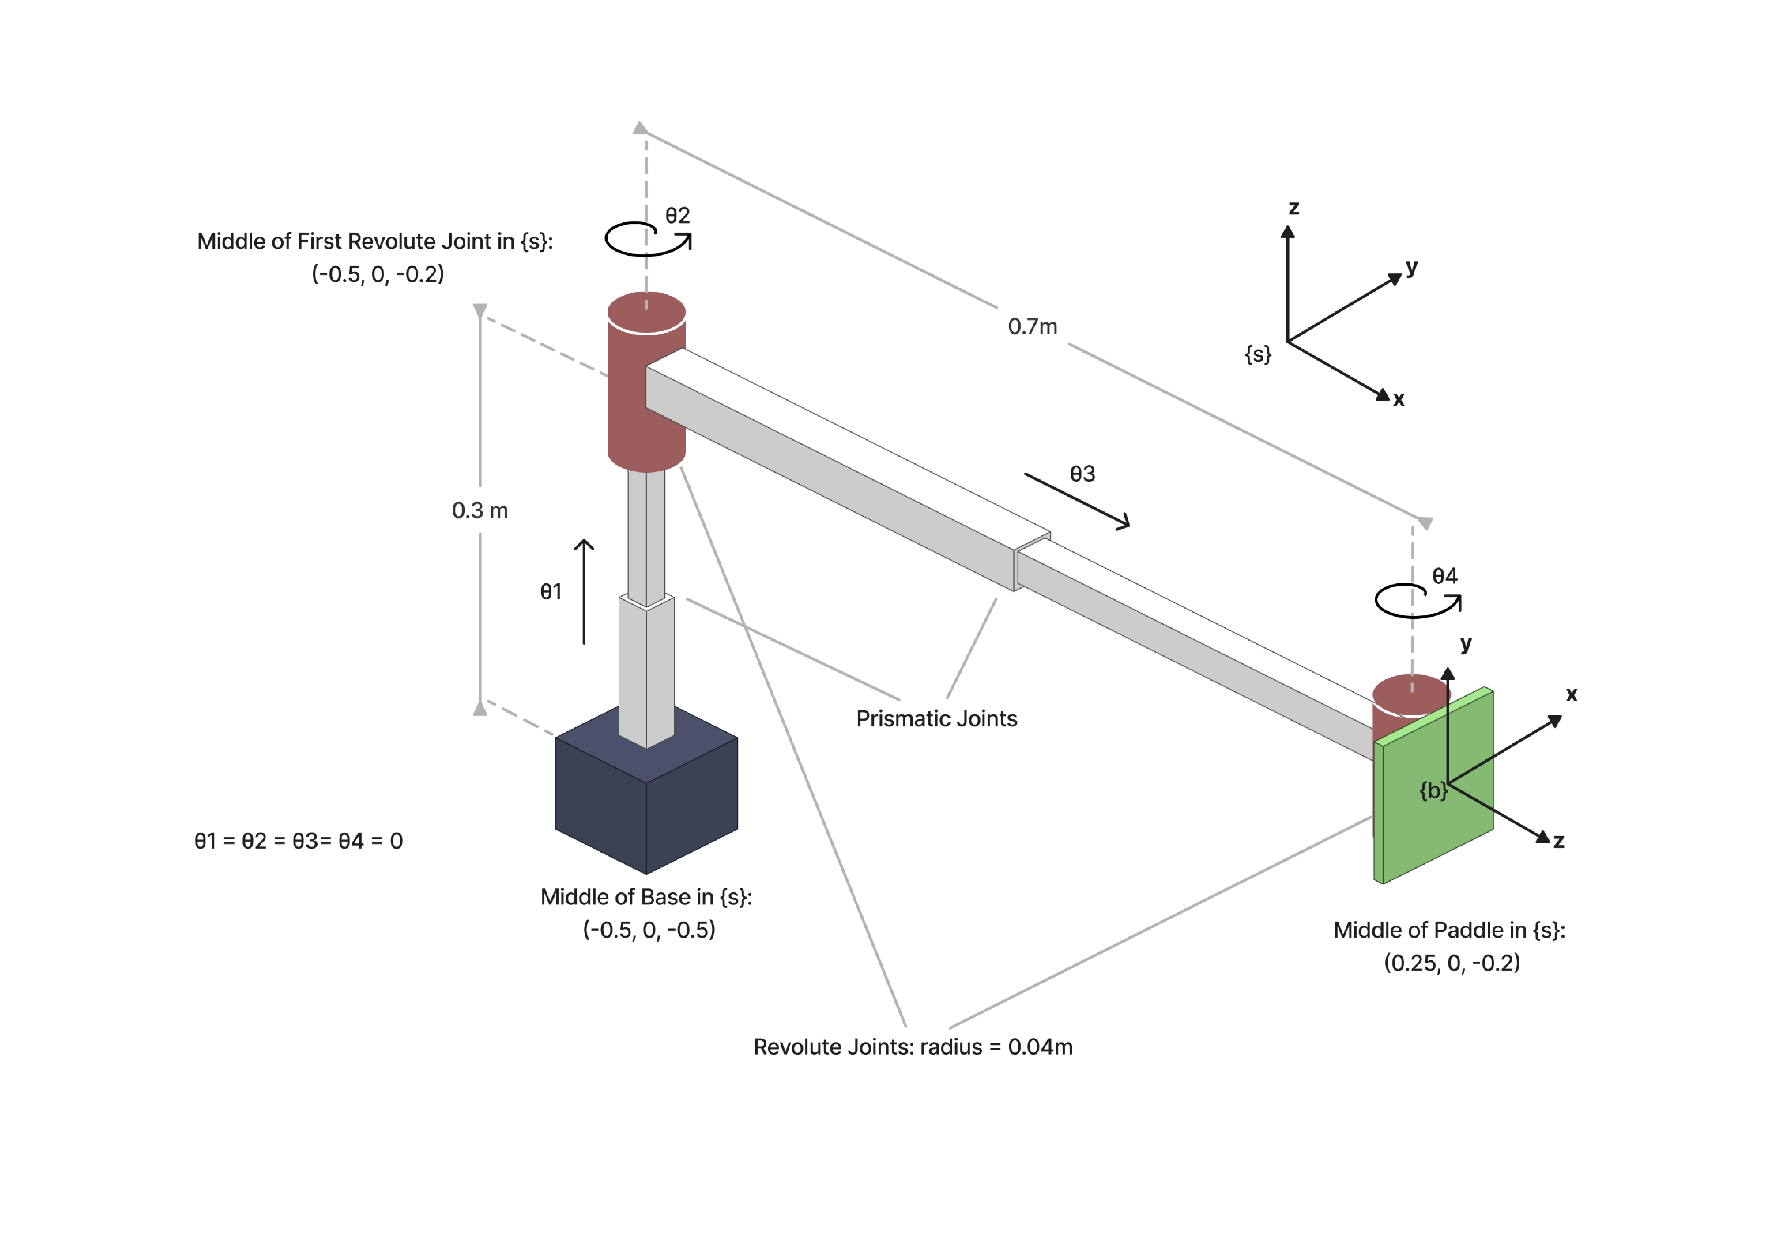

imshow(imread("ECE486 Project Design.png"))

The dimension of the first joint aligned with z-axis was chosen to be $L_1
$ = 0.3m tall while the second joint was chosen to be $L_2
$ = 0.7m. This was chosen to allow the reach of the arm to be far enough into the vertical edges on the far side of the workspace. By inspection, we can see that the furthest point in the xy-plane{s} that the paddle needs to reach within the workspace are the positions where the xy coordinates are either [1.1, 0.8] or [1.1, -0.8], which describe the furthest edges from the closest centre points of the cuboid. This gives us the inequality 


$$\sqrt{(L_2 + 0.8)^2 + 0.8^2} \le 1 + L_2$$


where the LHS denotes the hypotnuse of the triangle relative to centre of the cuboid from the sky view and the RHS refers to the maximum length that the arm can reach relative to $J_2$. Solving for this equation gives $L_2 \ge 0.7
$. Adding this length on top of the radius of the revolute joint(4cm) and the thickness of the paddle(1cm), we have an effective distance of 0.75 meters. This gives a good safety buffer for the robot to reach all xy-coordinates within the cuboid. Furthermore, given that $J_1$has a range betwen 0 and 1 meters, we can reach all z-coordinates between -0.2 to 0.8 in {s}.

Lastly, given a range of $-\pi/2$ and $\pi/2$ for $J_4$, and the max angle for $J_2$ is less than $tan^{-1}(0.8/0.7) = 0.85 rad$, we can confidently say that any orientation between -15 to 15 degrees can be achieved for the paddle at any configuration for the rest of the joints within the workspace.

Singularities occurs at the range limits of the joints. In this case, the limits happen $\forall [\theta_1,\theta_2,\theta_3,\theta_4]$, where $\theta_1 = \{0,1\}\lor \theta_2 = \{-\pi,\pi\} \lor \theta_3 = \{0,1\} \lor \theta_4 = \{-\pi/2,\pi/2\} $. By inspection, we can say that within the limits, there are no singularities within the workspace. That is, the exist no configuration within the workspace where the robot looses its ability to move in any direction.

## 2. Defining the Arm and Its manipulability

The following outlines the joints and the screw axis for each joint, as well as the matrix for the initial position $M$.


% Define joint_types, joint_limits, S_list, B_list, and M
joint_types = ['P','R','P','R']; 
% J1 => Prismatic, J2 => Revolute, J3 => Prismatic, J4 => Revolute

n_joints = length(joint_types);
joint_limits = [[0;1],[-pi;pi],[0;1],[-pi/2;pi/2]];

% Screw axis in fixed and paddle frames bases off of the design in part 1
S_list = [[0;0;0;0;0;1],[0;0;1;0;0.5;0]  ,[0;0;0;1;0;0],[0;0;1;0;-0.2;0]];
B_list = [[0;0;0;0;1;0],[0;1;0;0.75;0;0],[0;0;0;0;0;1],[0;1;0;0.05;0;0]];

% Initial Posiiton in SE(3)
M = [0 0 1 0.25; 
     1 0 0 0; 
     0 1 0 -0.2; 
     0 0 0 1];

manipFun = @manipulability;

We can use this definition to analyze the manipulability of the arm at various configurations within the workspace in the following 5 diagrams. We can see that all angular manipulabillity ellipsoids have zero volume due to the prismatic joints in our design. However, we're not in a singularity since the linear ellipsoids are still volumous, where the thickness of the elliposids tells us how much we can move the end-effector at any direction.

- Paddle at the home position as outlined in the Task section:

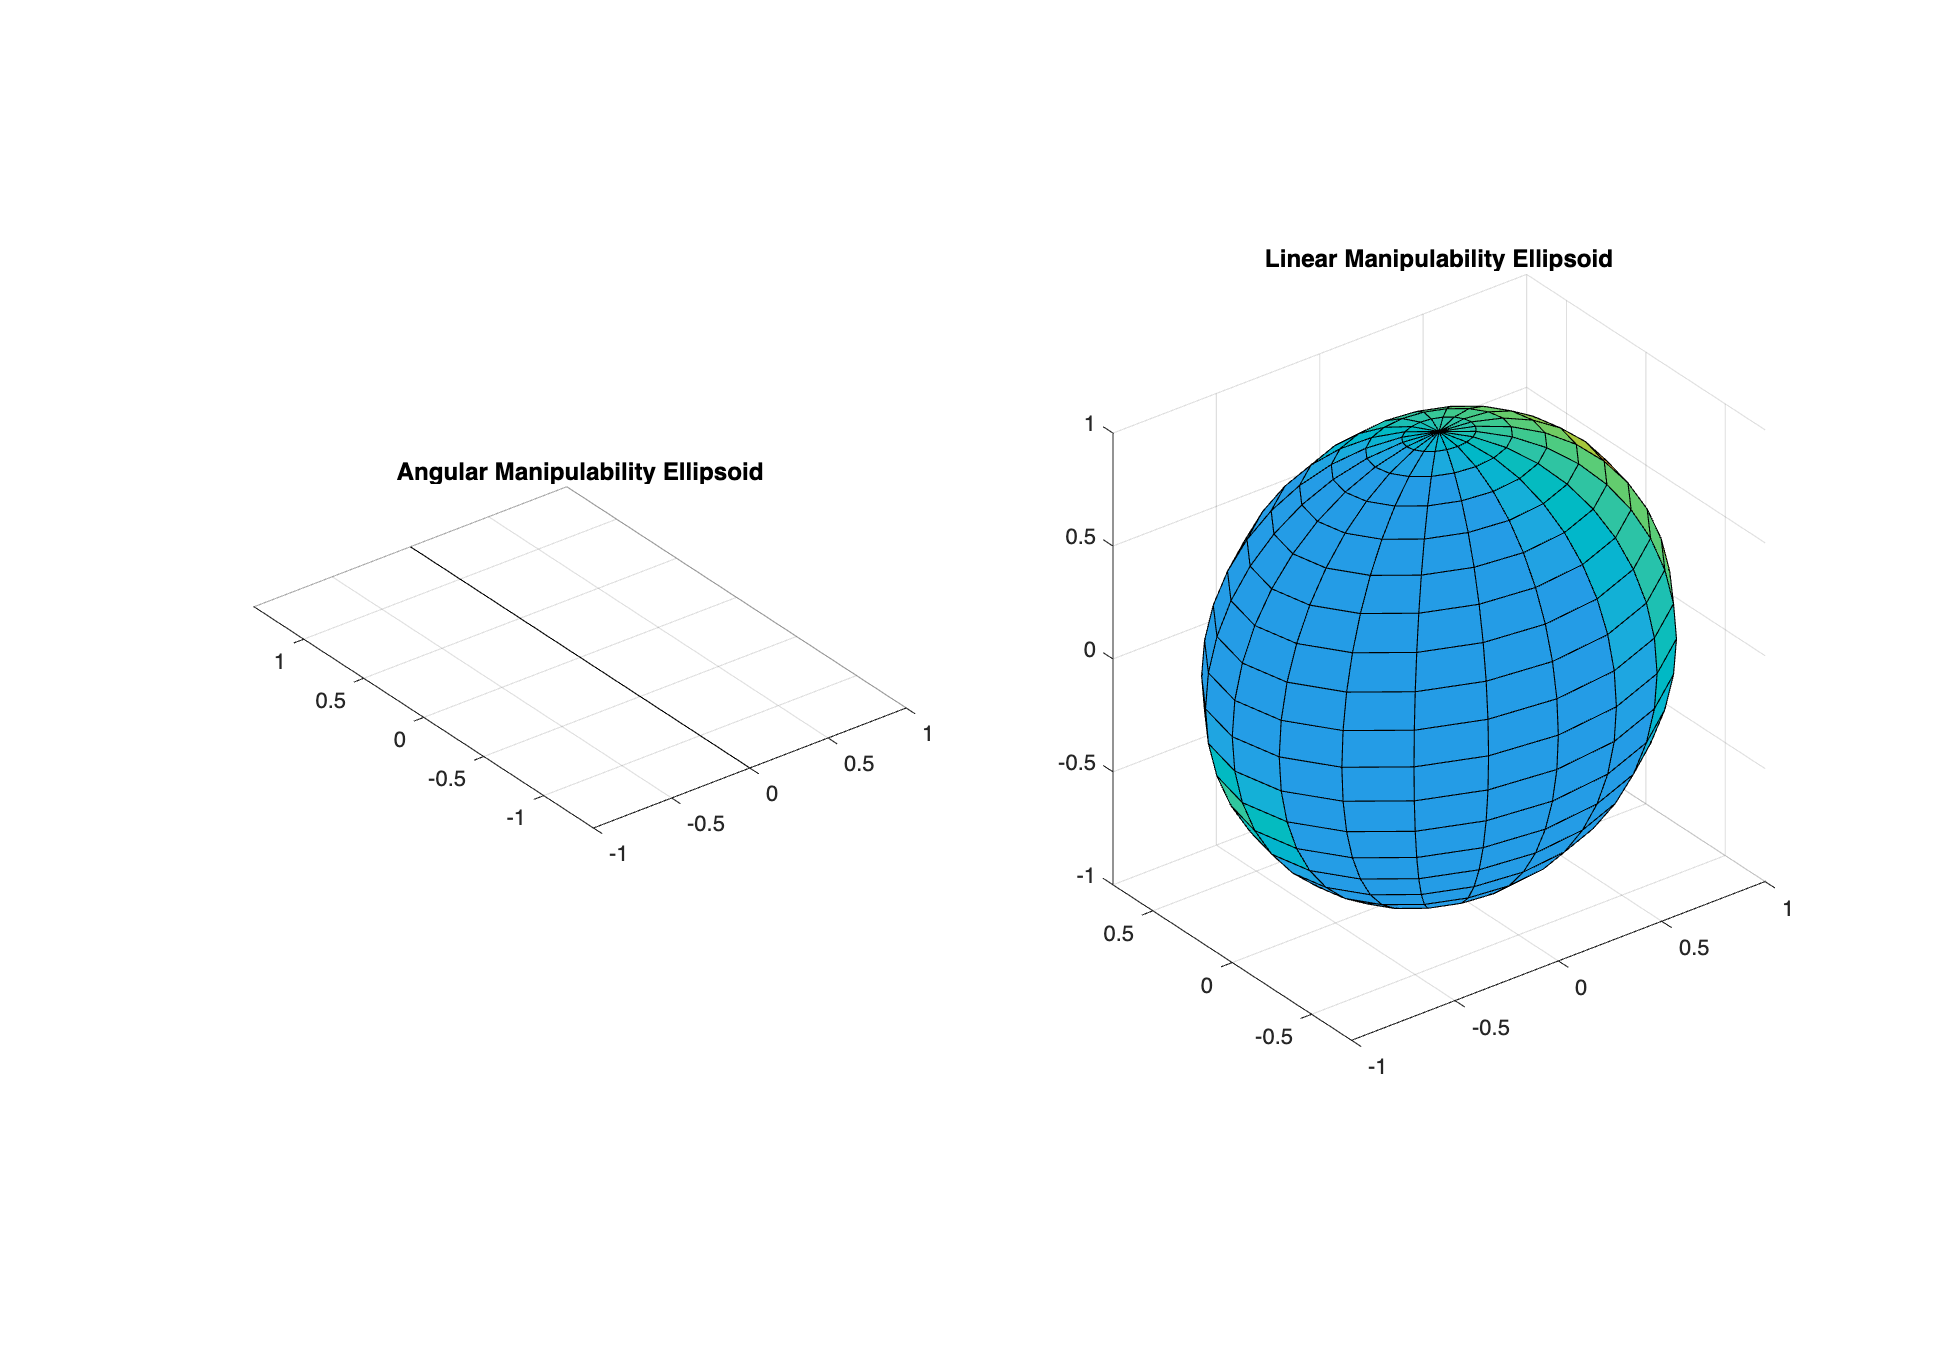

theta_list0 = [0.4, 0, 0, 0];
J_B0 = JacobianBody(B_list, theta_list0);
[at_singularity0, mu_angular0, mu_linear0] = manipulability(J_B0, theta_list0);

    2. Paddle at the centre of the workspace, not tilted:

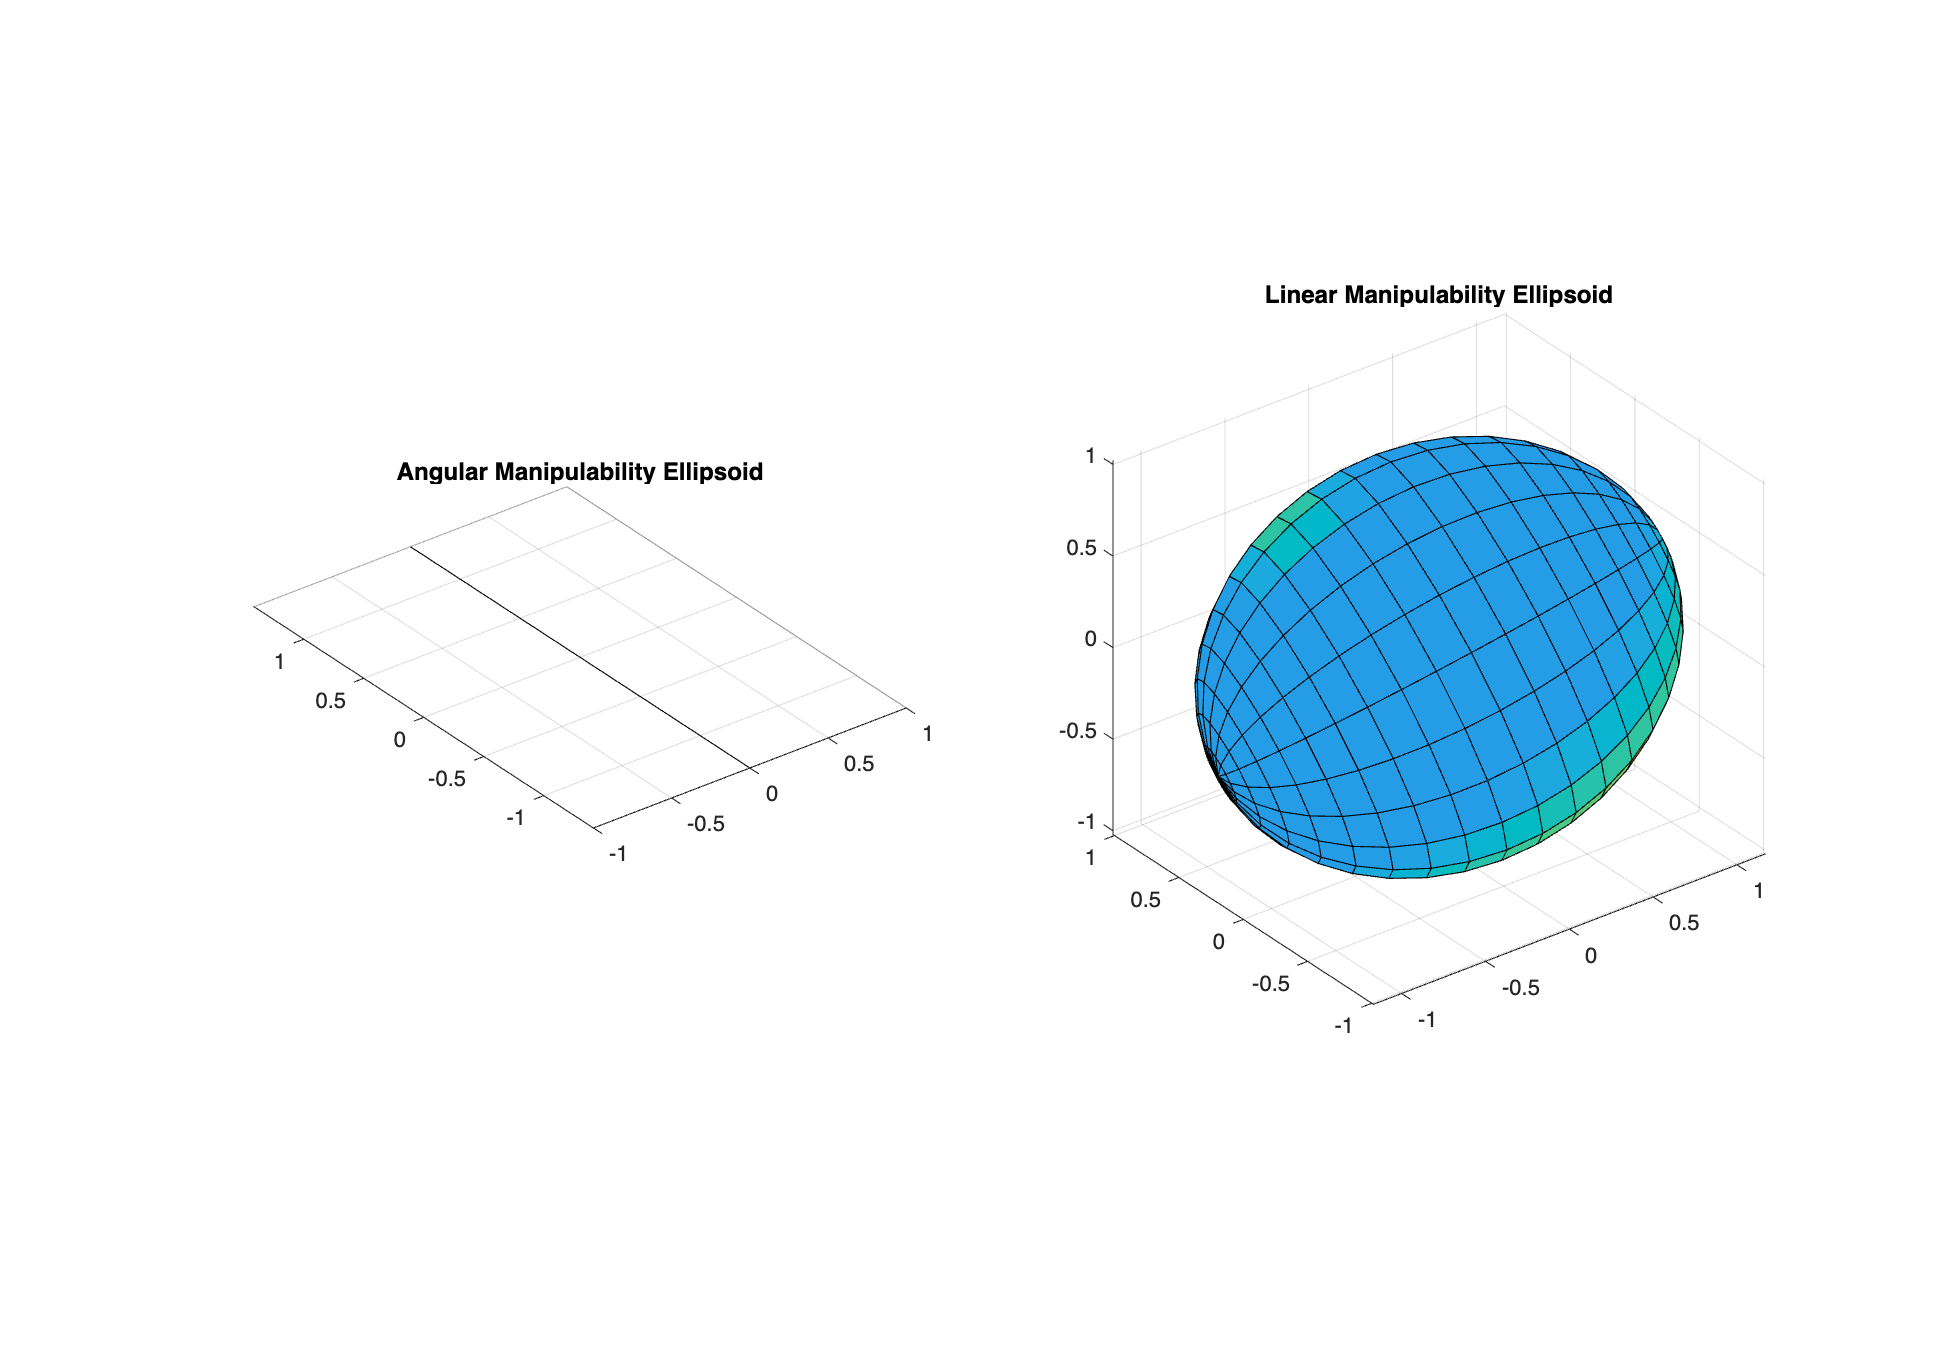

theta_list1 = [0.5, 0, 0.45, 0];
J_B1 = JacobianBody(B_list, theta_list1);
[at_singularity1, mu_angular1, mu_linear1] = manipulability(J_B1, theta_list1);

    3. Paddle close to the left lower corner on the far side of the workspace, with no tilt

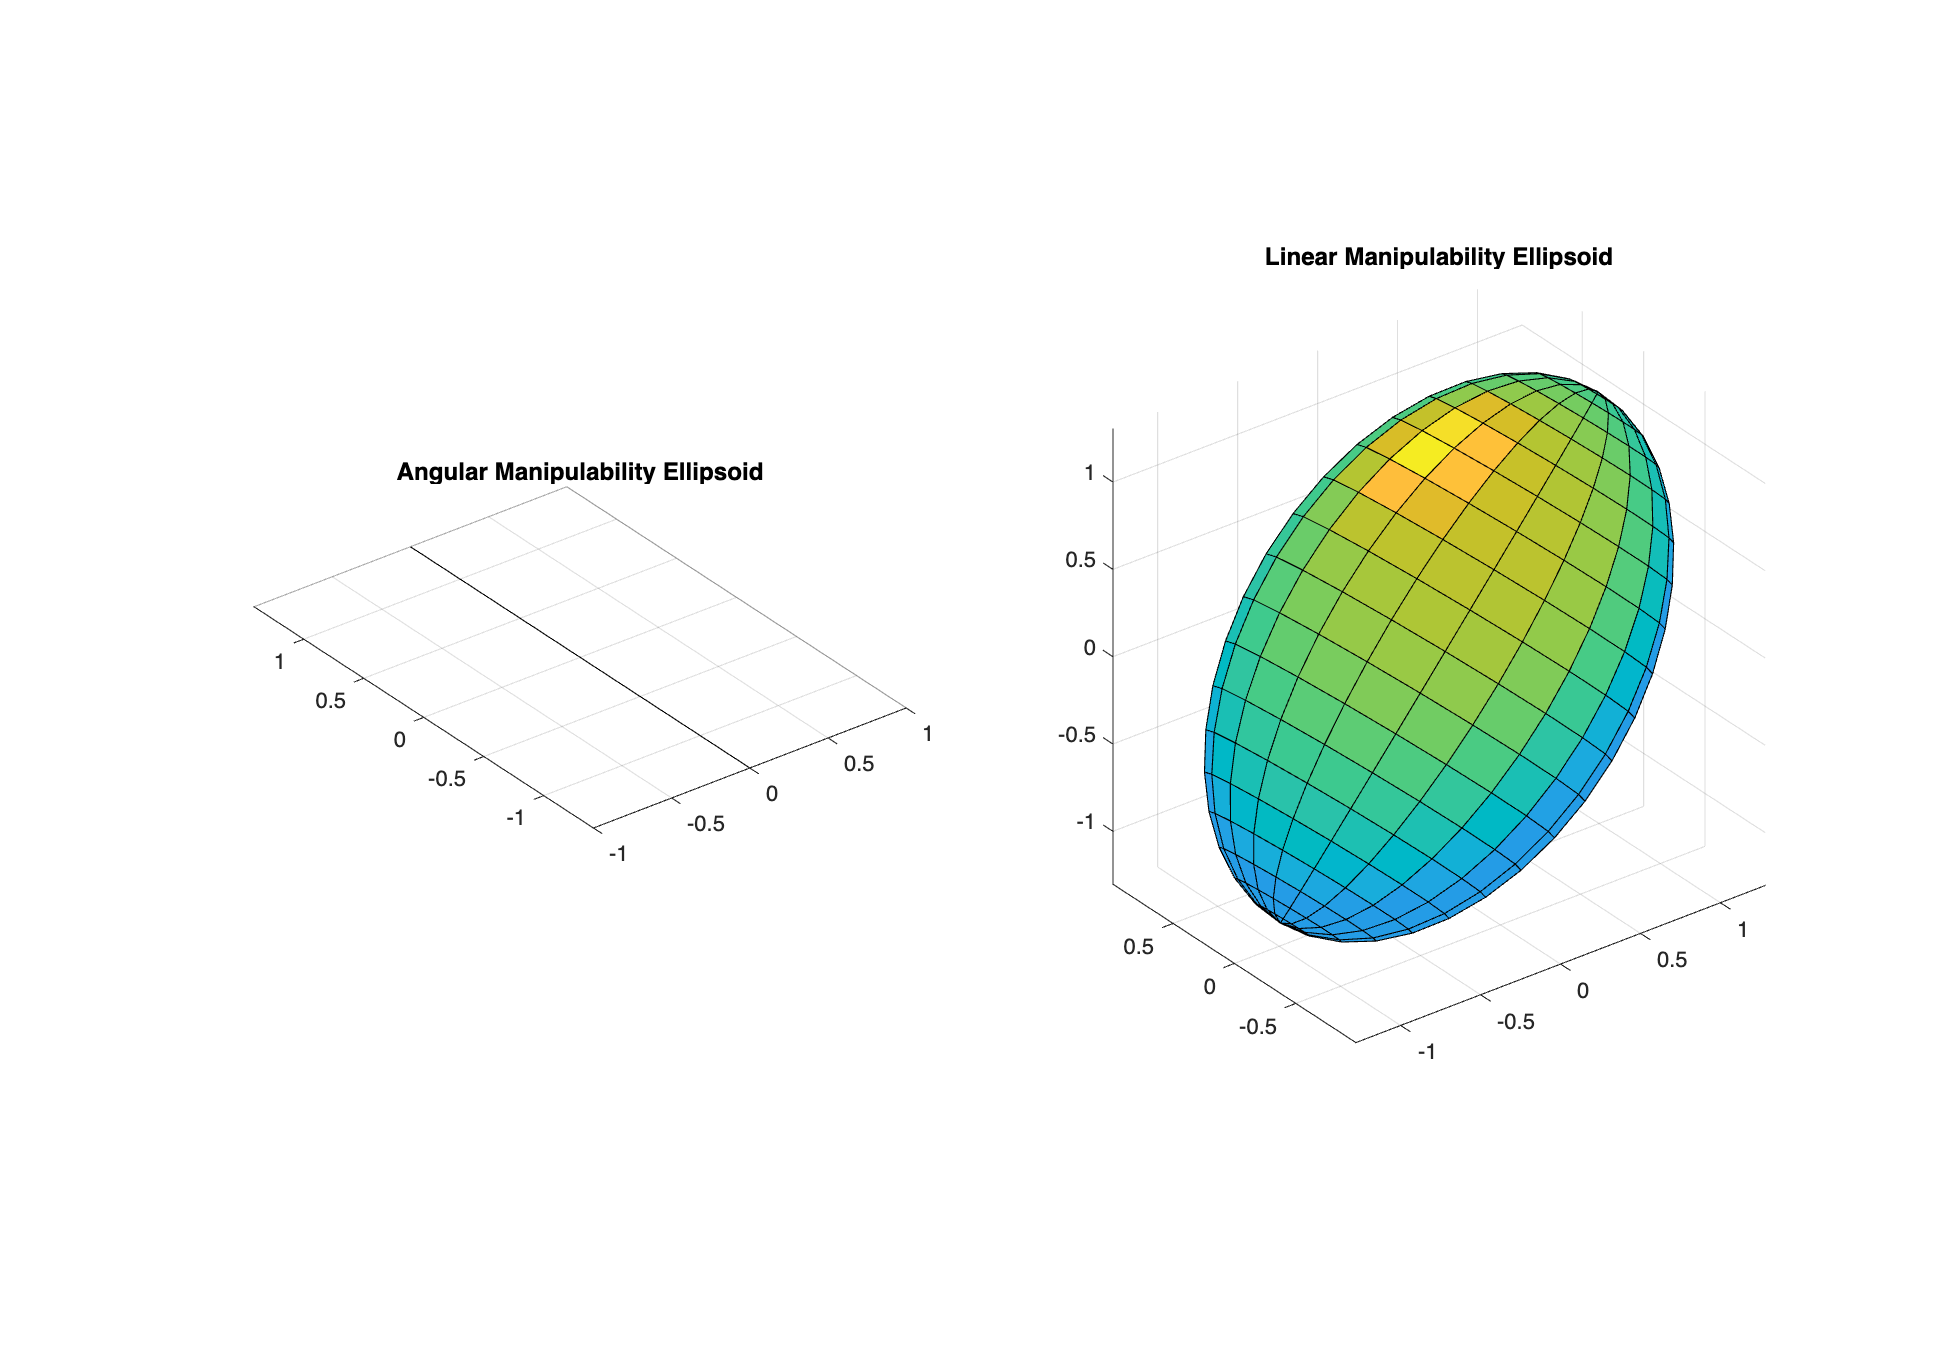

theta_list2 = [0.8, -pi/4, 0.8, pi/4];
J_B2 = JacobianBody(B_list, theta_list2);
[at_singularity2, mu_angular2, mu_linear2] = manipulability(J_B2, theta_list2);

    4. Paddle at the far lower edge of the workspace, tilted by 10 degrees

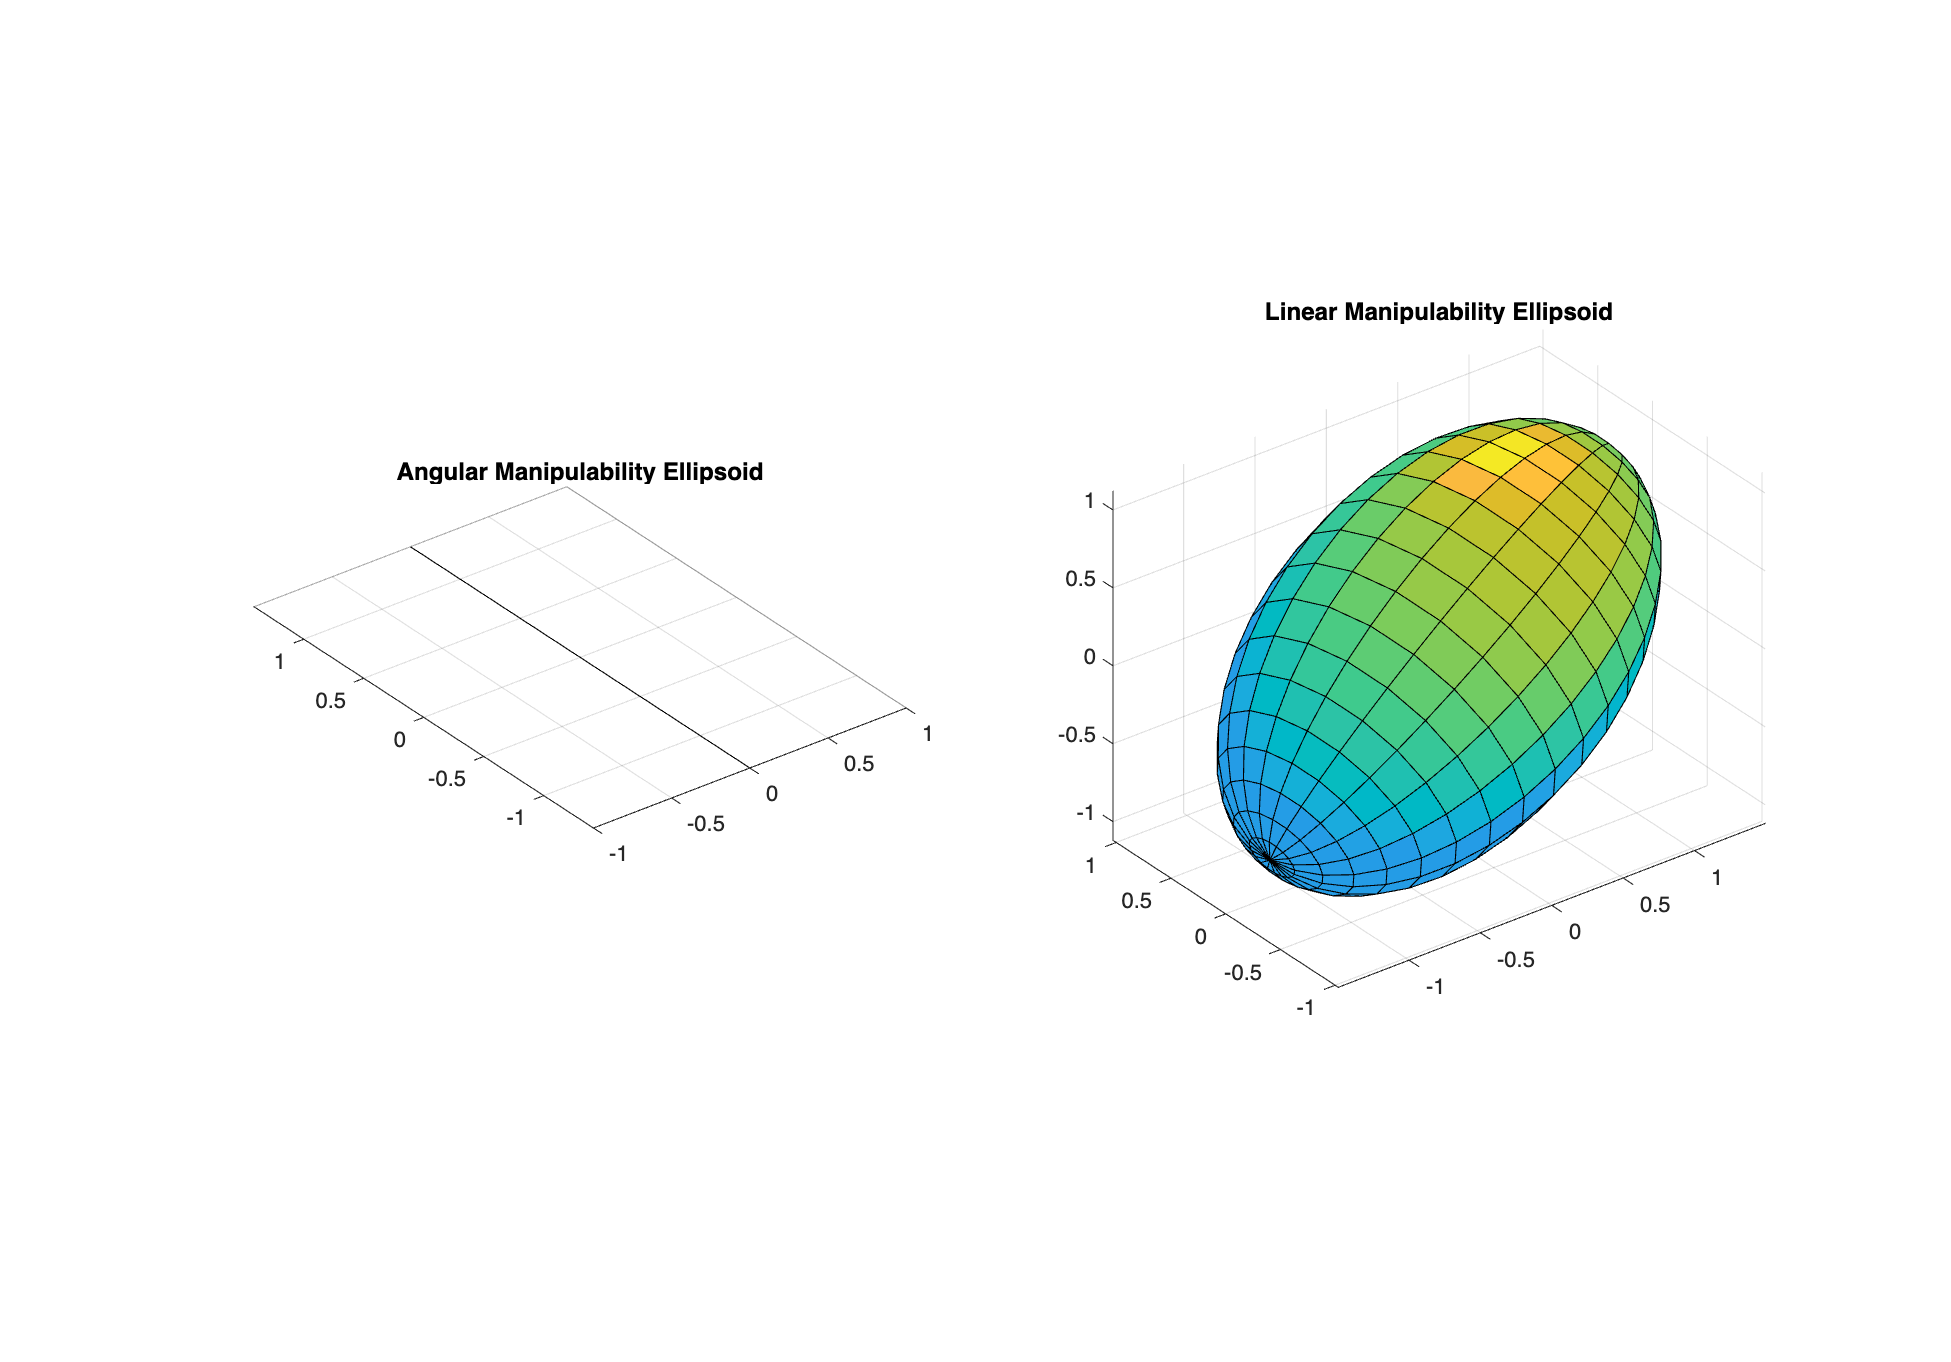

theta_list3 = [0, 0, 0.85, pi/18];
J_B3 = JacobianBody(B_list, theta_list3);
[at_singularity3, mu_angular3, mu_linear3] = manipulability(J_B3, theta_list3);

    5. Centre of paddle close to the right upper corner on the close side of the workspace, with no tilt

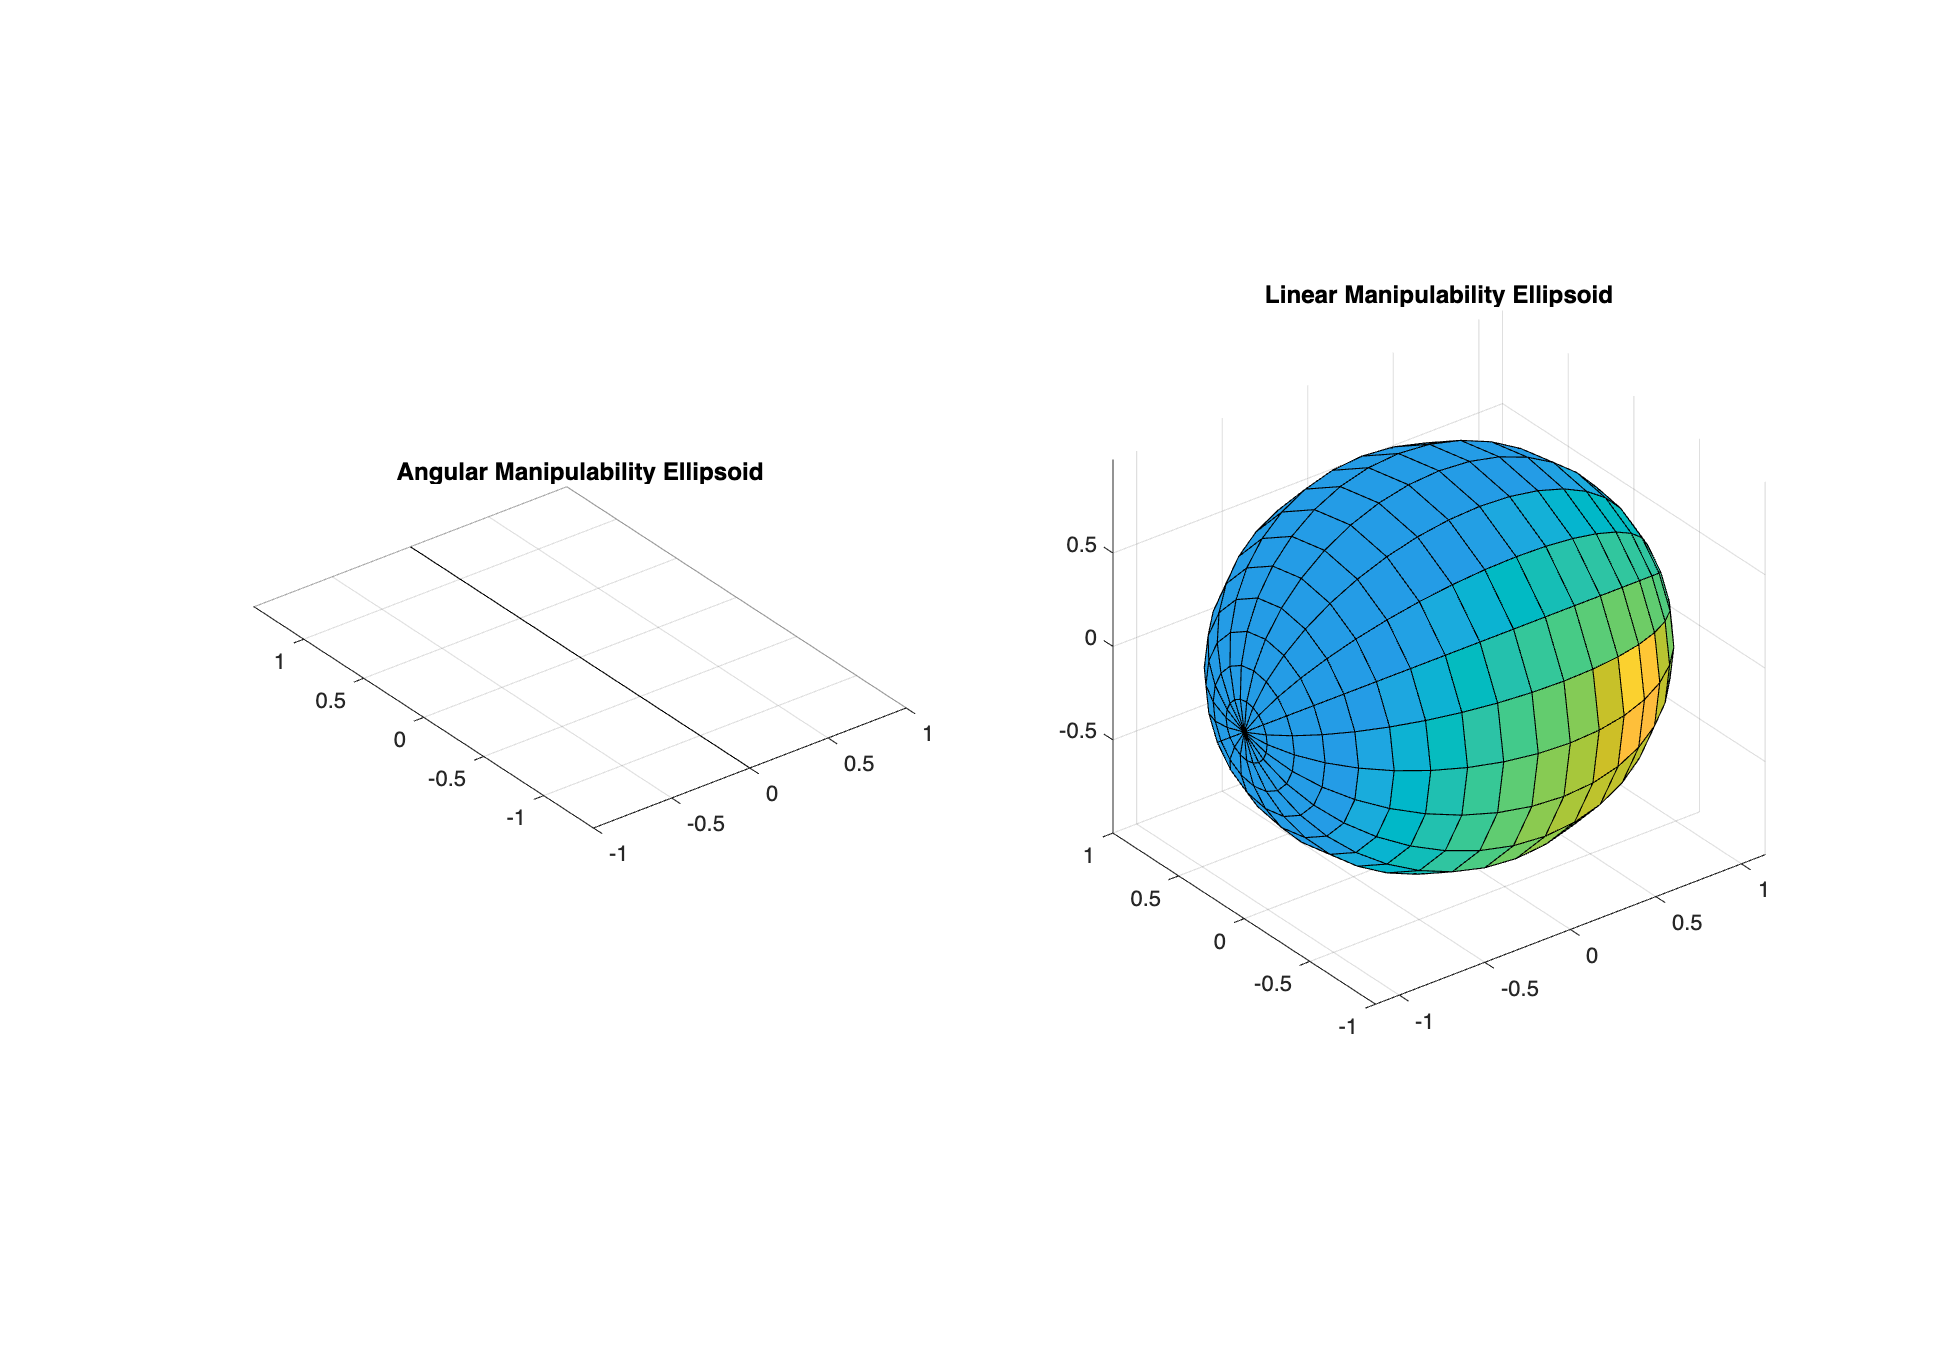

theta_list4 = [0.4, pi/4, 0.4, -pi/4];
J_B4 = JacobianBody(B_list, theta_list4);
[at_singularity4, mu_angular4, mu_linear4] = manipulability(J_B4, theta_list4);

## 3. Appendix: Manipulability function definition

The manipulability function is important to have in order to show whether or not we are close to any sigularities at any configuration of the robot when trying to intercept the ball. When considering the inverse kinematics in the upcoming sections, we need to know if the joint angles required for a given x, y, z cordinate of the ball is a suitable position for the robot to move into, and how that would affect its manipulability for the upcoming tasks. Furthermore, by examining the configuration within the workspace by looking at its manipulability, we can judge the design of the robot which would come handy in the upcoming validation parts of this project. For example, we can calculate the jacobian at any point in the trajectory that we generate to meet the a specific paddle pose. Then we can see, if at any point in the trajectory we are close to a singularity based on mu_angular and mu_linear, that the rest of the trajectory can be generated to avoid going into such singularities.

function [at_singularity, mu_angular, mu_linear] = manipulability(J_B, thetalist)
% Inputs:
% J_B - the Body Jacobian matrix for an arbitrary robot
% thetalist - a list of joint positions for the robot

% Seperate the Jacobian into its angular and linear components
J_Bw = J_B(1:3, :);
J_Bv = J_B(4:6, :);

% Get the A matrices for the jacobian
Aw = J_Bw * transpose(J_Bw);
Av = J_Bv * transpose(J_Bv);

% Diagnolizing the A matrices gives the eigenvalues and eigenvectors.
% This gives the axies for the ellipsoids.
[Vec_w,Eig_w] = eig(Aw);
[Vec_v,Eig_v] = eig(Av);
angular_manipulability_axes = sqrt(diag(Eig_w));
linear_manipulability_axes = sqrt(diag(Eig_v));
% display(Vec_w);
% display(Vec_v);

[x_ang, y_ang, z_ang] = ellipsoid(0, 0, 0, angular_manipulability_axes(1), angular_manipulability_axes(2), angular_manipulability_axes(3));
[x_lin, y_lin, z_lin] = ellipsoid(0, 0, 0, linear_manipulability_axes(1), linear_manipulability_axes(2), linear_manipulability_axes(3));

% Plot and rotate all ellipsoids base on eigenvectors
figure(1);
subplot(1,2,1);
S_ang = surfl(x_ang, y_ang, z_ang);
rw_axang = rotm2axang(Vec_w);
rotate(S_ang, rw_axang(1:3), rad2deg(rw_axang(4)));
title("Angular Manipulability Ellipsoid");
axis equal;
% display(rw_axang(1:3));
% display(rad2deg(rw_axang(4)));

subplot(1,2,2);
S_lin = surfl(x_lin, y_lin, z_lin);
rv_axang = rotm2axang(Vec_v);
rotate(S_lin, rv_axang(1:3), rad2deg(rw_axang(4)));
title("Linear Manipulability Ellipsoid");
axis equal;
% display(rv_axang(1:3));
% display(rad2deg(rv_axang(4)));

% Calculate the measures mu_1, mu_2, and mu_3 for both linear and angular motion
mu_1v = max(linear_manipulability_axes) / min(linear_manipulability_axes);
mu_2v = mu_1v.^2;
mu_3v = prod(linear_manipulability_axes, "all");

mu_1w = max(angular_manipulability_axes) / min(angular_manipulability_axes);
mu_2w = mu_1w.^2;
mu_3w = prod(angular_manipulability_axes, "all");

mu_linear = [mu_1v, mu_2v, mu_3v];
mu_angular = [mu_1w, mu_2w, mu_3w];

% Determine if the given thetalist places the robot in a singularity
J_rank = rank(J_B);
n_joints = length(thetalist);
at_singularity = 0;

if J_rank < n_joints
    at_singularity = 1;
end

end